# Ovarian Cancer Prediction

This Live Script demonstrates the use of the trained Ovarian Cancer model for predicting classes of "Normal" or "Cancer" for new patients.

### Load Data

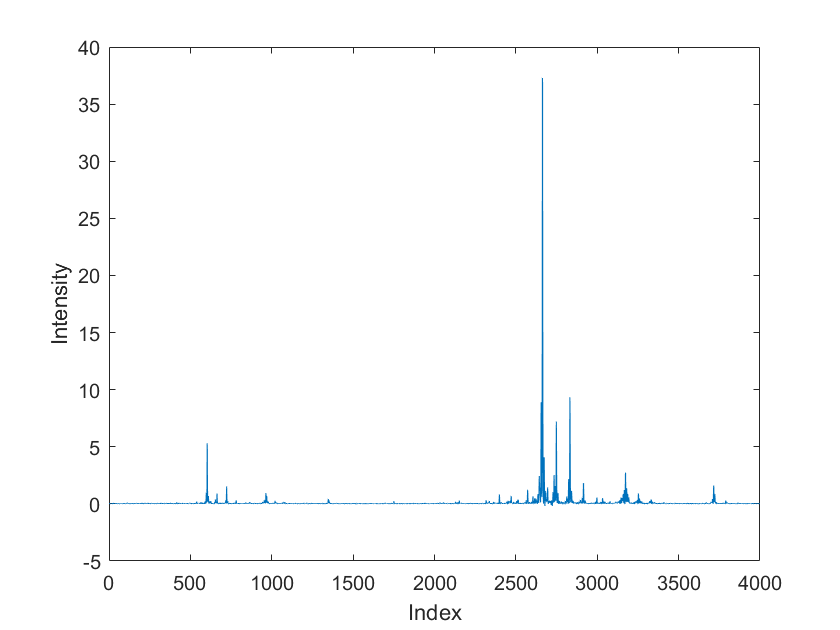

% Load new patient data
load data_7sBiUEE2q60f.mat patientData

% Load trained model and preprocessing data
load trainingResults.mat cancerModel meanObs stdObs selectedFeatures

% Visualize
plot(patientData)
xlabel("Index")
ylabel("Intensity")

### Preprocess Data

The two preprocessing steps are normalization (z-scores) and selecting predictive features. These features were chosen with a wrapper method using a KNN model.

% Normalize Data
processedData = (patientData - meanObs)./stdObs;

% Select Features
processedData = processedData(:,selectedFeatures);

### Make Prediction

The mode `cancerModel`l is a KNN model with 10 nearest neighbors. Use the code below to predicted "Cancer" or "Normal" this patient.

predictedClass = predict(cancerModel,processedData);
disp("The predicted class is: " + predictedClass)

The predicted class is: Cancer
